#  Sumas de Riemann 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Uno de los conceptos más importantes y útiles del cálculo es la idea de calcular la acumulación. En muchas situaciones, hay información sobre una tasa de cambio (por ejemplo, aceleración, velocidad, concentración, flujo, potencia) y el cálculo presenta herramientas para calcular la acumulación que ocurre (por ejemplo, velocidad, posición, cantidad, volumen, energía, etc.). ). 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña ** View ** de la barra de herramientas de MATLAB, en la sección ** View **, seleccione ** Hide Code**. Alternativamente, seleccione ** Hide Code ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Cálculo de la generación de energía solar 

###  Antecedentes 

 Considere la energía generada por un panel solar fijo con una potencia nominal máxima de 643,545 kW. Para convertir esta potencia (en kilovatios) en energía (kilovatios-hora) es necesario acumular esta potencia a lo largo del tiempo. 

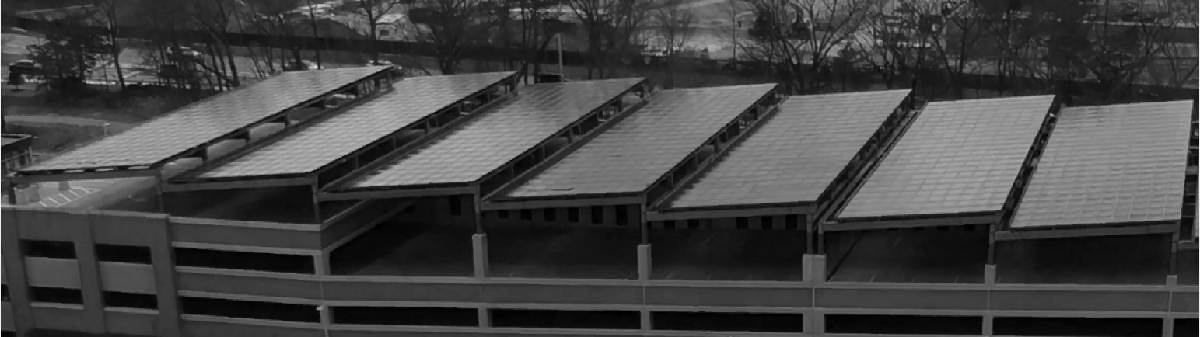

Datos del panel solar del estacionamiento del MathWorks Lakeside Campus, del 14 al 20 de marzo de 2021. 

figure;           % Inicializar una figura

% Cargue datos de generación de energía solar y preproceselo para realizar un seguimiento del tiempo.
Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
Data.Timestamp(1);
Data.Timestamp = Data.Timestamp-Data.Timestamp(1);

% Trazar los datos y etiquetar la gráfica y los ejes.
plot(days(Data.Timestamp), Data.AC_kw)
title("Power Generation, March 14-20 2021")
xticks(.5:1:6.5)
xticklabels(["Day 1" "Day 2" "Day 3" "Day 4" "Day 5" "Day 6" "Day 7"])
xlabel("Time since 00:00, March 14, 2021 (days)")
ylabel("Power in kilowatts (kw)")
 

####  Seleccione un día 

Elija un día para analizar más detenidamente. 

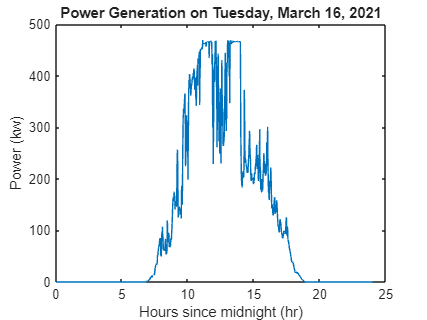

DesiredDay = 3;              
% Utilice un bloque try/catch para fallar correctamente si las secciones se ejecutan 
% sin orden . Alternativamente, esto podría incluir controles en vivo que ejecutan esta 
% sección y cualquier sección anterior modificada o que aún no se haya ejecutado.
try 
    [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(DesiredDay,Data);   % Comprobar si los datos están cargados
catch
    % Si el conjunto de datos aún no está cargado, hágalo aquí
    disp("You must load the data before you can analyze it.")
    disp("Loading data now ... to plot the full dataset, click the 'Load and Plot Data' button, above.")
    Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
    Data.Timestamp(1);
    Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
    disp("Data loaded, proceeding with analysis...")
    [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(DesiredDay,Data);
end

% Trace los datos seleccionados para un solo día y etiquete el gráfico y los ejes
% Incluya una nota especial para el día excepcionalmente corto debido al cambio de hora
% a EDT desde EST el 14 de marzo de 2021
figure
plot(DataHours,DataPower)
title("Power Generation on "+StrDay+", March "+DateDay+", 2021")
if DesiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)") 

Concéntrese en el período en el que no estaba oscuro, por lo que los paneles tenían posibilidades de generar electricidad. 

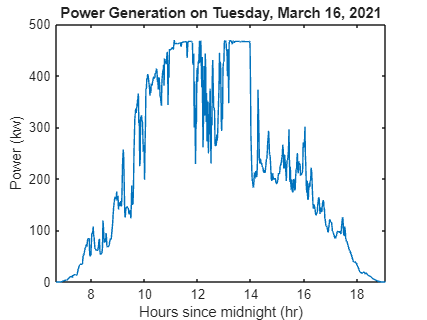

% Elimine los ceros iniciales y finales restringiéndolos a horas
% que se aproximan al amanecer y al atardecer
figure;
p1 = plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
xlim([6+2/3 19+1/12])
title("Power Generation on "+StrDay+", March "+DateDay+", 2021")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

###  Continuidad de conjuntos de datos 

 Este gráfico parece continuo, pero en realidad está interpolado linealmente entre cada punto de datos adyacente, generado por informes de sensores cada minuto a lo largo del día. Considere la representación del diagrama de dispersión: 

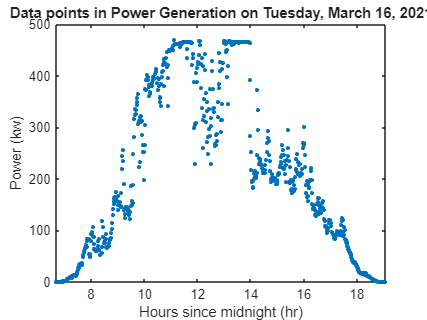

% Trazar los datos como puntos discretos para observar los valores de dispersión.
figure
p2 = plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset),".","MarkerSize",9);
xlim([6+2/3 19+1/12])
title("Data points in Power Generation on "+StrDay+", March "+DateDay+", 2021")
if DesiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

 ** Reflexione **

- ¿Qué tan fácil es ajustar una curva simple a estos datos? ¿Importa qué día de la semana se elige? 

- ¿La mayoría de los conjuntos de datos del mundo real son continuos o discretos? ¿Por qué? ¿Qué implicaciones tiene esto para el uso del cálculo en aplicaciones? 

- ¿Los datos subyacentes en esta situación, en la que los paneles solares generan energía, son continuos o discretos? 

##  Aplicación: Sumas de Riemann con aproximaciones rectangulares 

Estos datos proporcionan lecturas del sensor en intervalos de tiempo de un minuto en todo el día. Para calcular una aproximación de la cantidad de energía generada, es necesario sumar una aproximación de la potencia generada en cada intervalo de tiempo por la longitud del intervalo de tiempo. Visualmente, si seleccionamos una aproximación del extremo izquierdo: 

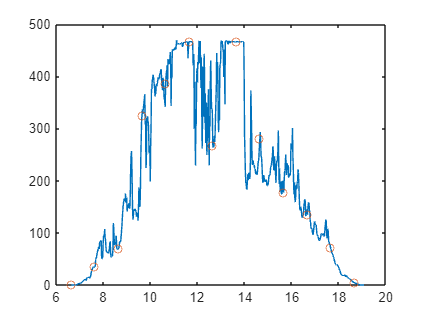

% Verifique si los datos están cargados en el espacio de trabajo y, si no, cárguelos
% para un día predeterminado del martes 16 de marzo de 2021, sin mostrar errores
if ~exist("Sunrise","var")              % Si no se elige un día, use el día deseado = 3 de forma predeterminada
    try
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
%         rootDir = fileparts(mfilename('ruta completa'))
        Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
        Data.Timestamp(1);
        Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    end
end

% Inicializar parámetros
Energy = 0;     % energía generada (kWh)      
dt = 1/60;      % Tamaño mínimo del paso de datos (horas)
End0 = length(DataHours(Sunrise:Sunset));
% Configure la duración del intervalo en múltiplos del tamaño de paso mínimo
Skip = 60;
% Seleccione el método de aproximación de valor de la suma de Riemann
EndPt = "left";     
% Grafique la aproximación de salida superpuesta a los datos.
figure
plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
hold on
plot(DataHours(Sunrise:Skip:Sunset),DataPower(Sunrise:Skip:Sunset),"o")

for k = Sunrise:Skip:Sunset
    xval = DataHours(k);
    if EndPt == "midpoint"
        if mod(Skip,2)==1
            % Si los datos se conocen en el punto medio del intervalo, utilícelos.
            Height = DataPower(k+(Skip+1)/2);
        else
            % If the data is not known, use linear interpolation to
            % estimate an appropriate value between the two nearest points
            Height = mean([DataPower(k+Skip/2) DataPower(k+Skip/2+1)]);
        end
    elseif EndPt == "left"
        % Seleccione el punto final izquierdo del intervalo. 
        Height = DataPower(k);
    elseif EndPt == "right"
        % Seleccione el punto final correcto del intervalo
        Height = DataPower(k+Skip);
    end
    % Dibuja el rectángulo en la parcela.
    rectangle("Position",[xval 0 Skip*dt Height],"EdgeColor","r");
    % Suma la energía aproximada generada en este intervalo al total
    Energy = Energy+Skip*dt*Height;
end
if EndPt == "midpoint"
    % Agregue estrellas negras que marquen los valores del punto medio de cada intervalo.
    DesiredPts = Sunrise:Skip:Sunset-Skip;
    if mod(Skip,2) == 1
        % Si los datos se conocen en el punto medio del intervalo, utilícelos.
        plot(DataHours(DesiredPts)+(Skip/2)*dt,DataPower(DesiredPts+(Skip+1)/2),"k*","MarkerSize",8)
    elseif mod(Skip,2) == 0
        % If the data is not known, use linear interpolation to
        % estimate an appropriate value between the two nearest points
        plot(DataHours(DesiredPts)+(Skip/2)*dt,(DataPower(DesiredPts+Skip/2)...
            +DataPower(DesiredPts+Skip/2+1))/2,"k*","MarkerSize",8)
    end
end
title("Energy Generation on "+StrDay+", March "+DateDay+", 2021")
subtitle("Estimated energy generated = "+Energy+"kwh, "+EndPt+" approximation")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")
hold off 

Observe que muchos de estos rectángulos sobreestiman (o subestiman) el valor de la energía generada durante ese período de tiempo. 

  ** Pruebe **. De forma predeterminada, este gráfico se genera con un tamaño de paso de 1 hora (60 minutos) y utiliza el punto final izquierdo para aproximar la potencia generada durante todo el intervalo. Intente seleccionar tanto la aproximación del punto final derecho como la aproximación del punto medio, además de acortar el tamaño del paso. 

 ** Reflexionar **. 

- ¿Qué método (punto final izquierdo, punto final derecho o punto medio) genera la aproximación más precisa a la energía total generada? 

- ¿Qué impacto tiene acortar el tamaño del paso en la estimación de energía total? ¿Importa si se utiliza una aproximación de punto final izquierdo, punto final derecho o punto medio? 

####  Visualización del error en aproximaciones de sumas de Riemann 

 Visualizar el error en cada paso requiere rastrear cuánto contribuye la sobreestimación y la subestimación a cada estimación. El área roja visualiza la sobreestimación de la producción de energía, mientras que el área verde visualiza la subestimación de la producción de energía. 

% Verifique si los datos están cargados en el espacio de trabajo y, si no, cárguelos
% para un día predeterminado del martes 16 de marzo de 2021, sin mostrar errores
if ~exist("Sunrise","var")              % Si no se elige un día, use el día deseado = 3 de forma predeterminada
    try
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
        Data = readtable("SolarPowerGeneration.csv","DateLocale","en_US");
        Data.Timestamp(1);
        Data.Timestamp = Data.Timestamp-Data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [DataHours,DataPower,Sunrise,Sunset,StrDay,DateDay] = ChooseDay(3,Data);
    end
end
dt = 1/60;   % Tamaño mínimo del paso de datos (horas)

% Seleccione el método de aproximación de la suma de Riemann
EndPt = "Left";   
MinSkip = 1;
for Skip=60:-1:MinSkip
    % Create 60 plots as individual frames showing how decreasing the step
    % size of "Skip" impacts the estimate of the energy generated
    Energy = 0;
    plot(DataHours(Sunrise:Sunset),DataPower(Sunrise:Sunset));
    hold on
    for k = Sunrise:Skip:Sunset
        xval = DataHours(k);
        if EndPt == "Midpoint"
            if mod(Skip,2)==1
                % Elija el valor del punto medio, si lo conoce
                Height = DataPower(k+(Skip+1)/2);
            else
                % Interpolate the midpoint value between adjacent known
                % values
                Height = mean([DataPower(k+Skip/2) DataPower(k+Skip/2+1)]);
            end
        elseif EndPt == "Left"
            % Seleccione el valor del punto final izquierdo para el intervalo
            Height = DataPower(k);
        elseif EndPt == "Right"
            % Seleccione el valor de punto final correcto para el intervalo
            Height = DataPower(k+Skip);
        elseif EndPt == "Maximum"
            % Seleccione el valor máximo conocido durante el intervalo
            Height = max(DataPower(k:k+Skip));
        elseif EndPt == "Minimum"
            % Seleccione el valor mínimo conocido durante el intervalo
            Height = min(DataPower(k:k+Skip));
        end
        % Plot the rectangular approximation using a maximally contrasting
        % color for either a dark or light background
        fig = gcf;
        MaxContastColor = round(1-fig.Color);
        rectangle("Position",[xval 0 Skip*dt Height],"EdgeColor",MaxContastColor);
        Energy = Energy+Skip*dt*Height;
        % Trazar la sobreestimación o subestimación en diferentes colores
        ViewRiemannBetween(DataHours(k:k+Skip),DataPower(k:k+Skip),Height)
    end
    title("Estimated Energy Generation of "+Energy+" kwh on "+StrDay+", March "+DateDay+", 2021")
    if Skip > 1
        subtitle(EndPt+" endpoint approximation, step = "+Skip+" minutes")
    else
        subtitle(EndPt+" endpoint approximation, step = "+Skip+" minute")
    end
    xlabel("Hours since midnight (hr)")
    ylabel("Power (kw)")
    hold off
    WaitTime = 0.2;
    pause(WaitTime);
    drawnow
end

  ** Pruebe **. 

- Cambie el método de aproximación al punto final derecho, punto medio, valor máximo y valor mínimo. 

- Cambia el día de la semana que estás estudiando. 

- Utilice el control deslizante o mire la animación para observar el impacto de aumentar/disminuir el tamaño del paso. 

 ** Reflexionar **. 

- ¿Qué observa sobre el error de los diferentes métodos de aproximación? 

- ¿Qué impacto tiene acortar el tamaño del paso en la estimación de energía total? ¿Importa qué tipo de estimación esté utilizando? ¿Por qué o por qué no? 

##  Suma de Riemann con aproximación trapezoidal 

Las aproximaciones de valores constantes suelen ser claramente malas aproximaciones, incluso a simple vista. Continuando con el tema de la aproximación de funciones mediante polinomios, después de una constante (polinomio de grado 0), la aproximación del polinomio de grado 1 es una recta. Usando los puntos finales de cada intervalo, esto nos da una aproximación trapezoidal del área bajo la curva. 

syms x
f(x) =  (x-5)*(x+2)*(x-7);
StepSize = 188; 
xVals = -5:.01:5;
fVals = f(xVals);
plot(xVals,fVals)
% fplot(f(x),[1 10],"k-","LineWidth",2)
hold on
SumTot = DisplayTrapezoidMethod(xVals,fVals,1,length(xVals),StepSize,.01);
title("Trapezoidal Method with step size "+StepSize*(xVals(2)-xVals(1)))
subtitle("")
hold off


###  Aplicación: Datos de energía solar 

Compare utilizando la aproximación trapezoidal de los datos de energía solar con diferentes tamaños de paso para obtener la mejor estimación posible dada la resolución de los datos. 

 
% Calcule y muestre la energía con diferentes tamaños de paso desde 1 hora hasta
% hasta 5 minutos usando la aproximación trapezoidal
Energy = DisplayTrapezoidMethod(DataHours,DataPower,Sunrise,Sunset,60:-5:5,1/60);
% Calcule la mejor estimación de energía disponible teniendo en cuenta los datos.
Height = (DataPower(Sunrise+1:Sunset)+DataPower(Sunrise:Sunset-1))/2;
Energy = [Energy;sum(Height*(1/60))];
% Cree una nueva gráfica de las estimaciones de generación de energía frente al tamaño del paso.
plot([60:-5:5 1],Energy)
hold on
% Agregue una línea para obtener la mejor estimación
yline(Energy(end),"r:")
title("Energy Generation Estimates compared to best")
xlabel("Step size (min)")
ylabel("Energy (kwh)")
legend(["Energy Estimate","Best Approximation"],"Location","northwest")
hold off


[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

La función `ChooseDay` devuelve el segmento de tiempo elegido del archivo de datos general. 

function [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = ChooseDay(desiredDay,data)
% ChooseDay selecciona una porción específica de información de los datos
% Entradas: Día deseado, un número entero correspondiente al día de la semana
% datos, una estructura de datos de serie temporal
% Salidas: horas de datos, una hora variable en horas
% dataPower, datos de producción de CA correspondientes en kilovatios
% amanecer, índice de amanecer aproximado en horas de datos
% atardecer, índice de atardecer aproximado en horas de datos
% strDay , una cadena que proporciona el nombre del día de la semana del día deseado
% dateDay, un número entero que indica el día del mes del día deseado
dayoffset = 24*60;
if desiredDay == 1
    startday = 1;
    sunrise = 5.75*60;            % la hora que falta es del cambio de hora
    sunset = 18*60;
    endday = dayoffset-60;        % la hora que falta es del cambio de hora
else
    startday = (desiredDay-1)*dayoffset-59;
    sunrise = 6.75*60-5;
    sunset = 19*60+5;
    endday = desiredDay*dayoffset-60;
end
dataHours = (days(data.Timestamp(startday:endday))-(desiredDay-1))*24;
dataPower = data.AC_kw(startday:endday);
weekday = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
strDay = weekday(desiredDay);
dateDay = 13+desiredDay;
end 

La función `ViewTrapBetween` configura las gráficas de aproximación trapezoidal. 

function ViewTrapBetween(xdata,fdata,skip)
% ViewTrapBetween calcula y dibuja una aproximación trapezoidal a fdata
% con una longitud de intervalo constante de salto entre valores de xdata
% Entradas: xdata es un vector de valores de variables independientes
% fdata es un vector de variables dependientes valores de variables wrt xdata
% skip es un número entero 

fdata = reshape(fdata,[1 length(fdata)]); % hacer de fdata un vector de fila
xdata = reshape(xdata,[1 length(xdata)]); % hacer de xdata un vector de fila

% hacer un vector de la pendiente desde el principio hasta el final de cada intervalo
slopes = (fdata(1+skip:skip:end)-fdata(1:skip:end-skip))./(xdata(1+skip:skip:end)-xdata(1:skip:end-skip)); 

% expanda los datos de pendiente para que coincidan con el tamaño de xdata con cada punto en el intervalo
% haciendo coincidir la pendiente para todo el intervalo
slopedata = reshape(slopes.*ones(skip,1),1,[]); % definir vector de pendientes en cada valor
if length(slopedata) < length(fdata)
    k = length(fdata)-length(slopedata);
    m = (fdata(end)-fdata(end-k))/(xdata(end)-xdata(end-k));
    restSlope = m.*ones(1,k);
    slopedata = [slopedata restSlope];
end

x0 = xdata(1:skip:end);                  % definir el valor de tiempo central para la línea tangente
x0data = reshape(x0.*ones(skip,1),1,[]); % definir el valor central asociado para cada punto
y0 = fdata(1:skip:end);                  % definir el valor de altura central para la línea tangente
y0data = reshape(y0.*ones(skip,1),1,[]); % definir el valor central asociado para cada punto

% Calcule los datos de altura correspondientes a la aproximación lineal por partes
% de fdata en intervalos de salto de longitud
heightdata = y0data(1:length(fdata)) + slopedata.*(xdata-x0data(1:length(fdata)));

% Trace la aproximación trapezoidal para cada intervalo y sombree el área extra
% (o faltante, respectivamente) de rojo (o verde). 
DrawColoredPolys(xdata,fdata,heightdata)
end 

La función `ViewRiemannBetween` traza el signo entre `fdata` y la línea `y=height`. 

function ViewRiemannBetween(xdata,fdata,height)
% ViewRiemannBetween calcula y dibuja un gráfico de fdata comparado con
% altura sobre el dominio de xdata
% Entradas: xdata es un vector de valores de variables independientes
% fdata es un vector de valores de variables dependientes wrt xdata
% la altura es un valor constante

fdata = reshape(fdata,1,[]); % hacer de fdata un vector de fila
xdata = reshape(xdata,1,[]); % hacer de xdata un vector de fila
heightdata = height*ones(size(fdata));
DrawColoredPolys(xdata,fdata,heightdata)
end 

La función `displayTrapezoidMethod` calcula el área aproximada y muestra un gráfico de la aproximación trapezoidal. 

function accumulation = DisplayTrapezoidMethod(xData,yData,startIdx,stopIdx,skipVals,dt)
% DisplayTrapezoidMethod muestra la aproximación de la 
% integral de yData dxData de xData(startIdx) a xData(stopIdx) 
% por tamaño skip para cada valor en skipVals Entradas: xData 
% es un vector de valores de variables independientes yData 
% es un vector de valores de variables dependientes startIdx 
% es el índice del límite inferior de la integral stopIdx 
% es el índice del límite superior de la integral *- --* 
% skipVals es un vector de valores de salto deseados dt da 
% el tamaño (con unidades) de un paso mínimo dx Salidas: 
% la acumulación es un vector de valores integrales aproximados 
% correspondiente a cada entrada en skipVals

accumulation = zeros(length(skipVals),1);
count = 1;
for skip=skipVals
    plot(xData(startIdx:stopIdx),yData(startIdx:stopIdx),"b-")
    plot([xData(startIdx) xData(stopIdx)], [0 0],"r-")
    numMissing = mod(length(yData(startIdx:stopIdx)),skip);
    if numMissing > 0
        if ~isrow(xData)
            % xData es una matriz de columnas; extiéndelo
            xAll = [xData(startIdx:skip:stopIdx);xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx);yData(stopIdx)];
        else
            % xData es una matriz de filas, extiéndela
            xAll = [xData(startIdx:skip:stopIdx),xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx),yData(stopIdx)];
        end
    else
        xAll = xData(startIdx:skip:stopIdx);
        yAll = yData(startIdx:skip:stopIdx);
    end
    hold on
    %% Manipulación cuidadosa del índice para construir un gráfico de aproximación trapezoidal
    tvals = reshape(xAll,1,[]).*ones(3,1);
    tAllVals = reshape(tvals,1,[]);
    pvals = reshape(yAll,1,[]).*[0;0;1];
    pParVals = reshape(pvals,1,[]);
    pAllVals = pParVals(2:end-1) + [pParVals(4:end) 0];
    tAllVals = tAllVals(2:end-1);
    plot(tAllVals,pAllVals,"r-")
    %% Calcular la altura efectiva de cada trapezoide.
    height = (yData(startIdx+skip:skip:stopIdx)+yData(startIdx:skip:stopIdx-skip))/2;
    accumulation(count) = sum(height*skip*dt);
    %% Tiene en cuenta el trapezoide adicional de menor ancho al final
    if numMissing > 0
        lastTrapHeight = (yData(stopIdx-numMissing)+yData(stopIdx))/2;
        accumulation(count) = accumulation(count)+lastTrapHeight*numMissing*dt;
    end
    ViewTrapBetween(xData(startIdx:stopIdx),yData(startIdx:stopIdx),skip)
    title("Trapezoidal Method with step size "+skip+" minutes")
    subtitle("Approximate Energy Generated "+accumulation(count)+" kwh")
    xlabel("Time (hrs)")
    ylabel("Power (kw)")
    pause(.5)
    count = count+1;
    hold off
end
end 

La función `DrawColoredPolys` determina las regiones donde la aproximación es demasiado grande o demasiado pequeña y las colorea en consecuencia. 

** Nota: ** Por defecto los colores utilizados son rojo y verde. Si desea utilizar otros colores en algunos lugares, digamos amarillo y morado, puede agregar los pares Nombre-Valor opcionales `OverColor` y `UnderColor`: 

o con amarillo y magenta: 

. Puede cambiar el valor predeterminado utilizado en todas partes. en este script editando los valores en `opts.OverColor` y `opts.UnderColor`. 

function DrawColoredPolys(xdata,fdata,heightdata,opts)
arguments
    xdata 
    fdata 
    heightdata 
    opts.OverColor = "r";
    opts.UnderColor = "g";
end
%% Determine las regiones donde los datos proporcionados por fdata son iguales,
% % por debajo o por encima de la aproximación dada por heightdata
sameHeight = fdata == heightdata;
isRed = fdata<heightdata;
isGreen = fdata>heightdata;
%% Identifique el inicio/final de cada región coloreada encontrando los índices
% % donde las regiones coloreadas comienzan/finalizan ya que la suma de compensación será 1 allí
sameHeightp = [0 sameHeight 0];
isRedp = [0 isRed 0];
isGreenp = [0 isGreen 0];
redSum = isRedp(1:end-1)+isRedp(2:end);
greenSum = isGreenp(1:end-1)+isGreenp(2:end);
equalSum = sameHeightp(1:end-1)+sameHeightp(2:end);
idxSwitch = find(redSum == 1 | greenSum == 1);
%% Verifique los puntos que se contaron dos veces porque pasaron por un punto de igualdad
idxCheck = find((idxSwitch(2:end)-idxSwitch(1:end-1))==1);
if nnz(idxCheck)>0
    for k = 1:length(idxCheck)
        if equalSum(idxCheck(k))==1 && equalSum(idxCheck(k)+1)==1
            idxSwitch = [idxSwitch(1:k) idxSwitch(k+2:end)];  % soltar interruptor adicional
        end
    end
end
%% Identificar índices donde ocurre un cambio de color entre puntos de datos
colorChange = find(greenSum == 1 & redSum == 1);

for k = 1:length(idxSwitch)-1    %% número de polígonos para crear
    if k == 1 && idxSwitch(k) ~= 1
        firstIdx = idxSwitch(k)-1;  % Corrige el índice inicial si el primer valor es la misma altura.
    else
        firstIdx = idxSwitch(k);
    end
    %% Configure los valores de x para los límites poligonales por encima/debajo de la línea de altura
    lastIdx = min([idxSwitch(k+1) length(xdata)]); %% ajustando por la indexación del último polígono
    %% Configure los valores de x para los límites poligonales, de izquierda a derecha y luego de derecha a izquierda
    xvals = [xdata(firstIdx:lastIdx) fliplr(xdata(firstIdx:lastIdx))];
    %% Set up the y values for the polygonal bounds above/below the height line
    %% To trace a continuous curve, the index ordering flips halfway through
    colorBetween = [fdata(firstIdx:lastIdx) heightdata(lastIdx:-1:firstIdx)];
    if nnz(colorChange == idxSwitch(k))  %% Compruebe si el punto inicial cambia de color entre puntos
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(idxSwitch(k))-heightdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calcular la pendiente de la línea de datos en esta región
        mf = (fdata(idxSwitch(k))-fdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calcule el valor de x donde la línea de datos y la línea de altura se cruzan en esta región
        xinterp = (heightdata(idxSwitch(k))-fdata(idxSwitch(k)))/(mf-mh)+xdata(idxSwitch(k));
        %% Append the interpolated values properly to include the additional triangle
        %% at the beginning/end of the polygon
        xvals = [xinterp xvals xinterp]; %#ok<AGROW> 
        height = mh*(xinterp-xdata(idxSwitch(k)))+heightdata(idxSwitch(k));
        colorBetween = [height colorBetween height]; %#ok<AGROW> 
    end
    if nnz(colorChange == idxSwitch(k+1)) %% Compruebe si el punto final cambia de color entre puntos
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(lastIdx)-heightdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calcular la pendiente de la línea de datos en esta región
        mf = (fdata(lastIdx)-fdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calcule el valor de x donde la línea de datos y la línea de altura se cruzan en esta región
        xinterp = (heightdata(lastIdx-1)-fdata(lastIdx-1))/(mf-mh)+xdata(lastIdx-1);
        %% Append the interpolated values properly to include the additional triangle
        %% midway through the polygon
        xvals = [xvals(1:end/2) xinterp xinterp xvals(end/2+1:end)];
        height = mh*(xinterp-xdata(lastIdx-1))+heightdata(lastIdx-1);
        colorBetween = [colorBetween(1:end/2) height height colorBetween(end/2+1:end)];
    end

    %% Traza los polígonos y elige el color de relleno deseado
    if isRed(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isRed(idxSwitch(k)+1))
        fill(xvals,colorBetween,opts.OverColor) %% Trazar regiones extra positivas OverColor
    elseif isGreen(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isGreen(idxSwitch(k)+1))
        fill(xvals,colorBetween,opts.UnderColor) %% Trazar regiones positivas faltantes UnderColor
    end
end
end